# Measuring Respiration and Pulse Rate Lab

## Introduction

Seismocardiography (SCG) is a non-invasive method that captures the mechanical activity of the heart by measuring chest wall vibrations using accelerometers. These vibrations occur during different phases of the cardiac cycle, such as the contraction of the ventricles and the movement of heart valves. The use of accelerometers for continuous heart monitoring is gaining popularity, especially for wearable healthcare devices.

Respiration rate, on the other hand, can be determined by detecting changes in the chest's orientation relative to Earth's gravitational field during breathing. As a person breathes, the expansion and contraction of the chest cause subtle changes in its angle and position, which can be captured by accelerometers sensitive to gravitational acceleration.

In this lab, you will work with real-world data collected during experiments with the Phyphox app to extract two crucial physiological metrics:

- **Pulse Rate (PR):** Measured using seismocardiography by capturing chest vibrations caused by the heart's mechanical activity.

- **Respiration Rate (RR):** Determined by detecting changes in the chest's angle relative to Earth's gravitational field during breathing movements.

You will preprocess the accelerometer data by resampling, perform spectral analysis to identify dominant frequency components, design filters based on spectral findings, and perform peak detection to calculate PR and RR. Additionally, you will explore the effects of motion artifacts by running the analysis on clean and artifact-induced data.

**Note:** You should perform the initial analysis and code development using the clean accelerometry signal, and then apply the same analysis on the signal with intentionally induced motion artifacts to observe the effects of noise on physiological signal processing.

**Learning Objectives:**

- Understand accelerometry and its applications in heart and respiration monitoring

- Perform spectral analysis to identify frequency components for PR and RR

- Design and apply filters based on spectral findings

- Perform peak detection and compute PR and RR

- Calculate time-averaged PR and RR over a standard 1-minute period

- Understand the impact of noise and motion artifacts on physiological signal analysis

## Signal Acquisitions

**Equipment:**

- Smartphone with Phyphox app

- Pulse Oximeter (PulseOx) sensor

- Stopwatch or timer

**Coordinate System:**

- Identify the smartphone's accelerometer axes

- Define the patient-fixed coordinate system

**Measurements:**

Perform the following measurements, each lasting at least 1 minute:

- **Measurement 1:** Upper chest, lying down in chair

- **Measurement 2:** Upper chest, sitting upright

- **Measurement 3:** Lower chest, lying down in chair

- **Measurement 4:** Lower chest, sitting upright

- **Measurement 5:** Introduce motion artifacts (e.g., slight movements) during the middle of the recording

**Instructions for Each Measurement:**

- Start recording with Phyphox

- Manually count breaths per minute or use a guided breathing pace

- Record pulse rate using the PulseOx sensor

- Export data as CSV files after each measurement

- Note chest position, body angle, breathing rate, and pulse rate

**Write down your results below:**

%% Student 1
% M1_PR = ; %Pulse Rate from PulseOx sensor
% M1_RR = ; % Respiration Rate from manual counting
% M2_PR = ;
% M2_RR = ;
% M3_PR = ;
% M3_RR = ;
% M4_PR = ;
% M4_RR = ;
% M5_PR = ;
% M5_RR = ;

%% Student 2
% M1_PR = ;
% M1_RR = ;
% M2_PR = ;
% M2_RR = ;
% M3_PR = ;
% M3_RR = ;
% M4_PR = ;
% M4_RR = ;
% M5_PR = ;
% M5_RR = ;

%% Student 3
% M1_PR = ;
% M1_RR = ;
% M2_PR = ;
% M2_RR = ;
% M3_PR = ;
% M3_RR = ;
% M4_PR = ;
% M4_RR = ;
% M5_PR = ;
% M5_RR = ;

## Data Analysis

### Step 0: Run MATLAB Commands for Clearing and Resetting

Before you begin, it is essential to clear all existing variables, close any open figures, and reset the command window to avoid conflicts and ensure a clean workspace.

close all;
clear;
clc;

### Step 1: Load and Inspect the Data

We will load the accelerometry  data, which contains acceleration signals along the X, Y, and Z axes. These signals capture the movement of the chest wall caused by pulsebeats and respiration.

**Exercise 1:** Modify the `folder_path` and `data_file` variables to match the location of your accelerometry data files.

% Set the current folder path (adjust as per your local directory)
folder_path = 'C:\Your\Directory\Here';  % <-- Modify this path
data_file = 'YourData.csv';        % <-- Modify this file name

% Load the clean accelerometry data with original column headers preserved
data = readtable(fullfile(folder_path, data_file), 'VariableNamingRule', 'preserve');

% Display column names 
disp(data.Properties.VariableNames)

    {'Time (s)'}    {'Acceleration x (m/s^2)'}    {'Acceleration y (m/s^2)'}    {'Acceleration z (m/s^2)'}    {'Absolute acceleration (m/s^2)'}



% Preview the first few rows of the data
head(data)

    Time (s)     Acceleration x (m/s^2)    Acceleration y (m/s^2)    Acceleration z (m/s^2)    Absolute acceleration (m/s^2)
    _________    ______________________    ______________________    ______________________    _____________________________

    0.0051869           0.15802                    3.9863                    8.8394                        9.698            
    0.0082648           0.15802                    3.9959                    8.8514                       9.7128            
     0.009291           0.16759                    4.0007                    8.8609                       9.7237            
     0.012262           0.18196                    4.0055                    8.8753                        9.739            
     0.013402           0.19154                    4.0031                    8.

### Step 2: Extract and Resample Time and Acceleration Signals

The accelerometry data may have non-uniform time intervals. For accurate signal processing, we need to ensure that the time intervals are uniform by resampling the data.

**Why Resample the Data?**

- **Uniform Sampling**: Many signal processing techniques assume the data is uniformly sampled. Non-uniform intervals can distort filtering and spectral analysis results

- **Interpolation**: Resampling ensures a consistent sampling frequency by interpolating the data over equally spaced time points

**Exercise 2:** Resample the time and acceleration signals from the `data`.

% Desired new sampling rate
fs_new = 125;  % Sampling rate in Hz

% Extract time and acceleration data from clean data
original_time = data.('Time (s)');               % Original time vector
acc_x = data.('Acceleration x (m/s^2)');         % Acceleration in X
acc_y = data.('Acceleration y (m/s^2)');         % Acceleration in Y
acc_z = data.('Acceleration z (m/s^2)');         % Acceleration in Z

% Ensure original_time_clean is a column vector
original_time = original_time(:);

% Create a new uniform time vector for clean data
%% Hint: Create a new time vector time_clean that starts at original_time_clean(1), ends at original_time_clean(end), and has increments of 1/fs_new seconds.
% --- Your code here ---
time = ;

Invalid expression. Check for missing or extra characters.

% Interpolate the acceleration data to the new time vector for clean data
%% Hint: Use the interp1 function to interpolate the acceleration data (acc_x_clean, acc_y_clean, acc_z_clean) to the new time vector time_clean.
% --- Your code here ---
acc_x = interp1();
acc_y = interp1();
acc_z = interp1();

% Optional: Confirm the new sampling rate
fs_check = 1 / mean(diff(time));
disp(['Sampling Rate: ', num2str(fs_check), ' Hz']);

Sampling Rate: 125 Hz


### **Step 3: Understanding the Acceleration Axes**

The accelerometry sensor records acceleration along three orthogonal axes:

- **X-Axis (Lateral Movement)**: Captures side-to-side movements

- **Y-Axis (Superior-Inferior Movement)**: Primarily captures chest movement during respiration

- **Z-Axis (Anterior-Posterior Movement)**: Captures the mechanical vibrations of the heart

**Why Use the Y and Z Axes?**

- **Respiration Rate (RR)**: The Y-axis is sensitive to the chest's expansion and contraction during breathing

- **Pulse** **Rate (PR)**: The Z-axis captures subtle vibrations associated with the pulsebeat

Understanding which axis corresponds to each physiological signal is essential for accurate PR and RR estimation.

### **Step 4: Visualizing the Raw Data**

Plot the data along the X, Y, and Z axes to understand the signal characteristics.

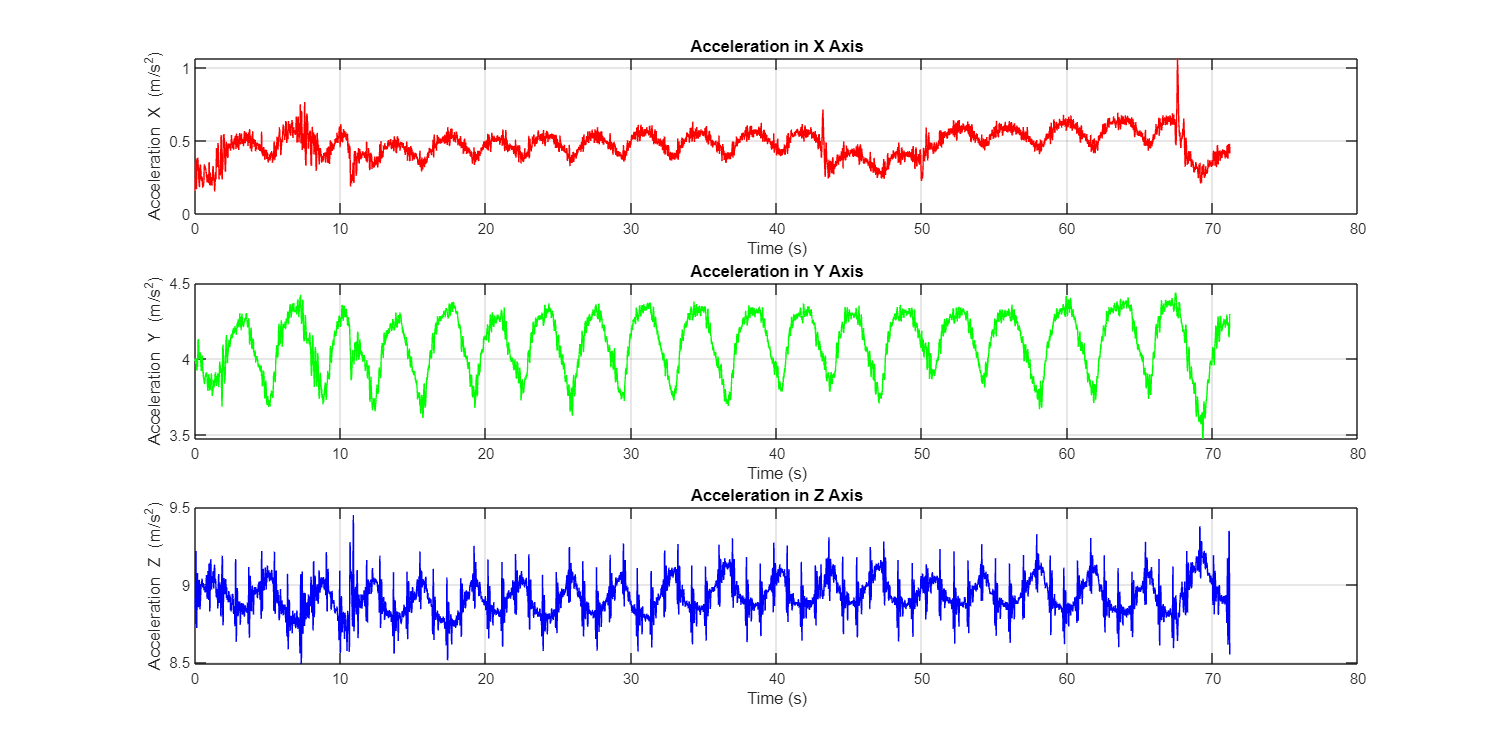

% Plot the data
figure('Position',[100, 100, 1200, 600]);  % Create a larger figure window

subplot(3, 1, 1);
plot(time, acc_x, 'r');
title('Acceleration in X Axis');
xlabel('Time (s)');
ylabel('Acceleration X (m/s^2)');
grid on;

subplot(3, 1, 2);
plot(time, acc_y, 'g');
title('Acceleration in Y Axis');
xlabel('Time (s)');
ylabel('Acceleration Y (m/s^2)');
grid on;

subplot(3, 1, 3);
plot(time, acc_z, 'b');
title('Acceleration in Z Axis');
xlabel('Time (s)');
ylabel('Acceleration Z (m/s^2)');
grid on;

% Enable interactive zooming
zoom on;  % Turns on zooming for this figure

### **Step 5: Spectral Analysis**

Spectral analysis transforms a time-domain signal into its frequency-domain representation, allowing us to identify dominant frequency components related to physiological processes, such as pulse beats and respiration.

**Why Perform Spectral Analysis?**

- **Identify Dominant Frequencies:** Pulse rate and respiration rate correspond to specific frequency ranges

- **Filter Design:** Helps in determining the appropriate cutoff frequencies for filtering

**Theoretical Background:**

- **Fourier Transform (FFT):** Converts a time-domain signal into the frequency domain

- **Power Spectral Density (PSD):** Represents how the power of a signal is distributed over different frequencies

- **Periodogram:** Estimates the PSD using the squared magnitude of the FFT

**Exercise 3:** Perform spectral analysis on the acceleration signals to identify the dominant frequency components.

**Instructions:**

- Compute the PSD of `acc_y` and `acc_z` using the `periodogram` function

- Plot the PSDs and identify the frequency ranges where significant peaks occur

- Use these observations to determine the expected frequency ranges for PR and RR

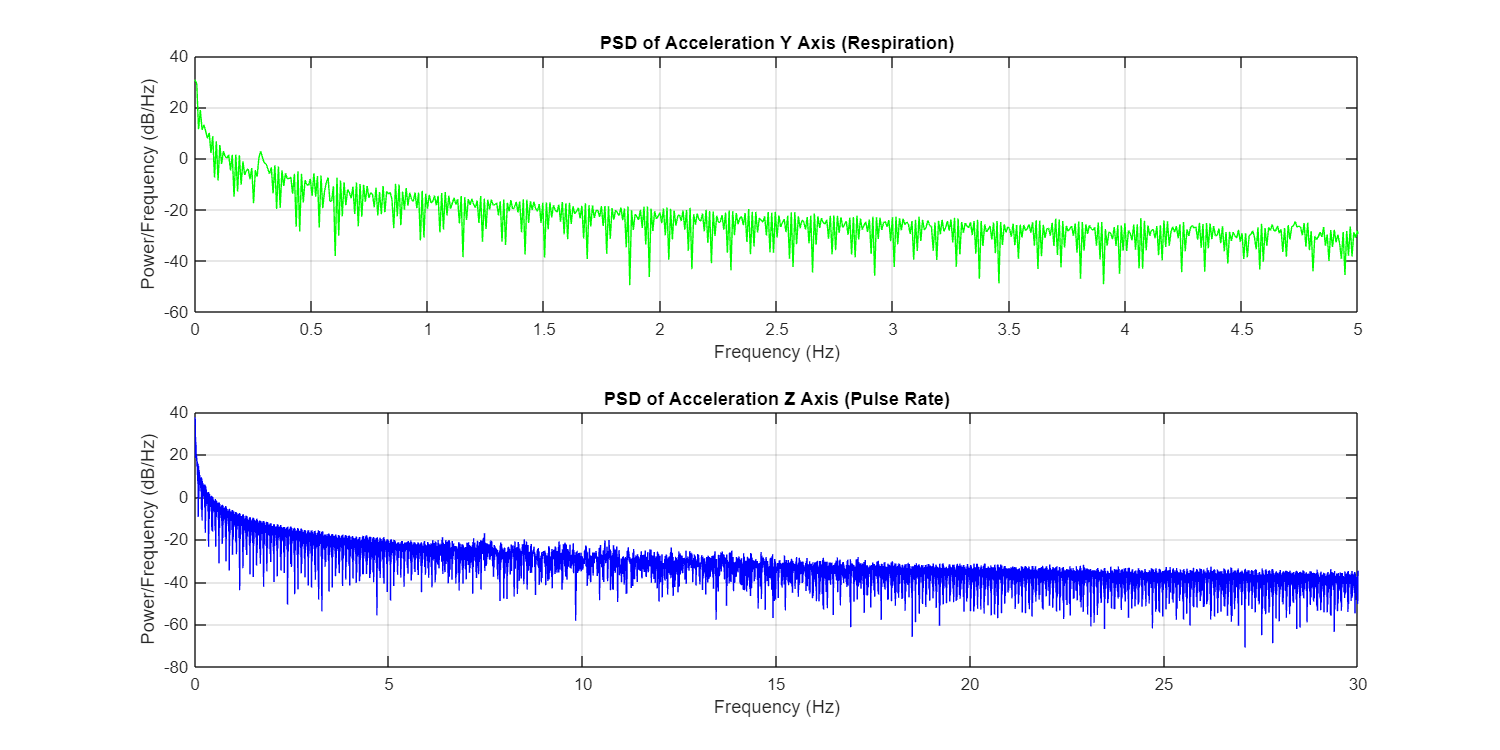

% Sampling frequency
fs = fs_check;

% Compute the Power Spectral Density (PSD) of the acceleration signals
% Hints:
% - Use the periodogram function: [Pxx, F] = periodogram(signal, [], [], fs);
% - Focus on acc_y for respiration and acc_z for pulse rate

% --- Your code here ---
% Compute PSD for acc_y (respiration axis)
[Pxx_y, F_y] = periodogram();

% Compute PSD for acc_z (pulse rate axis)
[Pxx_z, F_z] = periodogram();


% Plot the PSD for each axis
figure('Name', 'Power Spectral Density of Acceleration Signals', 'Position', [100, 100, 1200, 600]);

subplot(2,1,1);
plot(F_y, 10*log10(Pxx_y), 'g');
xlim([0 5]);  % Limit the x-axis to 5 Hz for respiration
title('PSD of Acceleration Y Axis (Respiration)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

subplot(2,1,2);
plot(F_z, 10*log10(Pxx_z), 'b');
xlim([0 30]);  % Limit the x-axis to 30 Hz for pulse rate
title('PSD of Acceleration Z Axis (Pulse Rate)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

% Enable interactive zooming
%zoom on;  % Turns on zooming for this figure

**Interpreting the Spectral Analysis:**

- **RR:** Typically corresponds to frequencies between** 0.1 Hz and 0.5 Hz** (6 bpm to 30 bpm)

- **PR:** In SCG signals, the mechanical vibrations of the heart produce frequency components typically ranging from **5 Hz to 20 Hz** due to mechanical events within each pulsebeat

**Questions:**

- Based on the PSD plots, what are the dominant frequency ranges for respiration and pulse rate?

- How do these ranges compare to typical physiological values?

### **Step 6: Filter Design and Parameter Selection**

Based on the spectral analysis, design bandpass filters to isolate the pulse rate and respiration rate signals.

**Filter Parameters for Respiration Rate:**

- **Low cutoff frequency (f_rl):** Set slightly below the lowest significant frequency identified for respiration

- **High cutoff frequency (f_rh):** Set slightly above the highest significant frequency identified for respiration

**Filter Parameters for Pulse Rate:**

- **Low cutoff frequency (f_hl):** Set slightly below the lowest significant frequency identified for pulse rate

- **High cutoff frequency (f_hh):** Set slightly above the highest significant frequency identified for pulse rate

**Exercise 4:** Choose appropriate cutoff frequencies for the bandpass filters based on your observations from Exercise 3.

**Instructions:**

- Determine the low and high cutoff frequencies for both respiration and pulse rate filters

- Justify your choices based on the PSD plots

- Design Butterworth bandpass filters using the `butter` function

% -- Respiration Rate Filter Parameters --
% Set cutoff frequencies based on spectral analysis
f_rl = ;   % Example low cutoff frequency for respiration (Hz)
f_rh = ;   % Example high cutoff frequency for respiration (Hz)

% -- Pulse Rate Filter Parameters --
% Set cutoff frequencies based on spectral analysis
f_pl = ;   % Example low cutoff frequency for pulse rate (Hz)
f_ph = ;   % Example high cutoff frequency for pulse rate (Hz)

% Normalize cutoff frequencies
% --- Your code here ---
Wn_rr = ;
Wn_pr = ;

% Set the order of the filters
order_rr = ;  % Order of the filter for respiration
order_pr = ;  % Order of the filter for pulse rate

% Design Butterworth bandpass filters
% --- Your code here ---
[b_rr, a_rr] = butter();
[b_pr, a_pr] = butter();

**Questions:**

- Why did you choose the specific cutoff frequencies for the filters?

- How does the filter order affect the filter's performance?

### Step 7: Apply Filters to the Signals

**Exercise 5**: Apply the designed filters to the appropriate axes: Y-axis for respiration rate and Z-axis for pulse rate.

**Instructions**:

- Try using both the `filter` and `filtfilt` functions to apply the filters

- Use the `filter` function, which applies the filter in the forward direction only

- Then, try the `filtfilt` function, which applies the filter in both forward and reverse directions to achieve zero-phase filtering

- Filter the Y-axis signal with the respiration filter and the Z-axis signal with the pulse rate filter

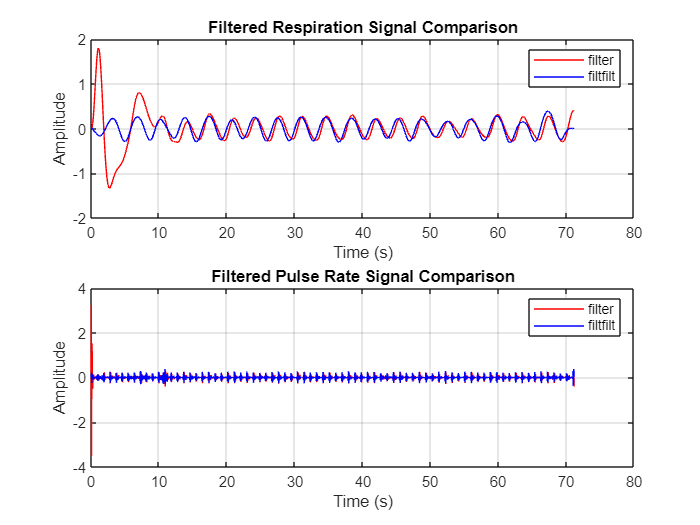

% Apply filters using filter (forward only) and filtfilt (zero-phase filtering)

% -- Apply filters using "filter" (forward only filtering) --
% Filtered respiration signal (using filter)
filtered_rr_filter = filter();
% Filtered pulse rate signal (using filter)
filtered_pr_filter = filter();

% -- Apply filters using "filtfilt" (zero-phase filtering) --
% Filtered respiration signal (using filtfilt)
filtered_rr_filtfilt = filtfilt();
% Filtered pulse rate signal (using filtfilt)
filtered_pr_filtfilt = filtfilt();

% Plot the results for comparison
figure;
subplot(2, 1, 1);
plot(time, filtered_rr_filter, 'r'); hold on;
plot(time, filtered_rr_filtfilt, 'b');
title('Filtered Respiration Signal Comparison');
legend('filter', 'filtfilt');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
plot(time, filtered_pr_filter, 'r'); hold on;
plot(time, filtered_pr_filtfilt, 'b');
title('Filtered Pulse Rate Signal Comparison');
legend('filter', 'filtfilt');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

**Reflective Questions**:

- Observe the filtered signals using both methods. What differences do you notice in terms of phase shift and signal distortion?

- Why might `filtfilt` be advantageous for our application in measuring PR and RR from accelerometry data?

- What could be potential disadvantages of using `filtfilt` in some applications?

### **Step 8: Visualizing the Filtered Signals**

Plot the filtered signals to inspect the outcome of filtering.

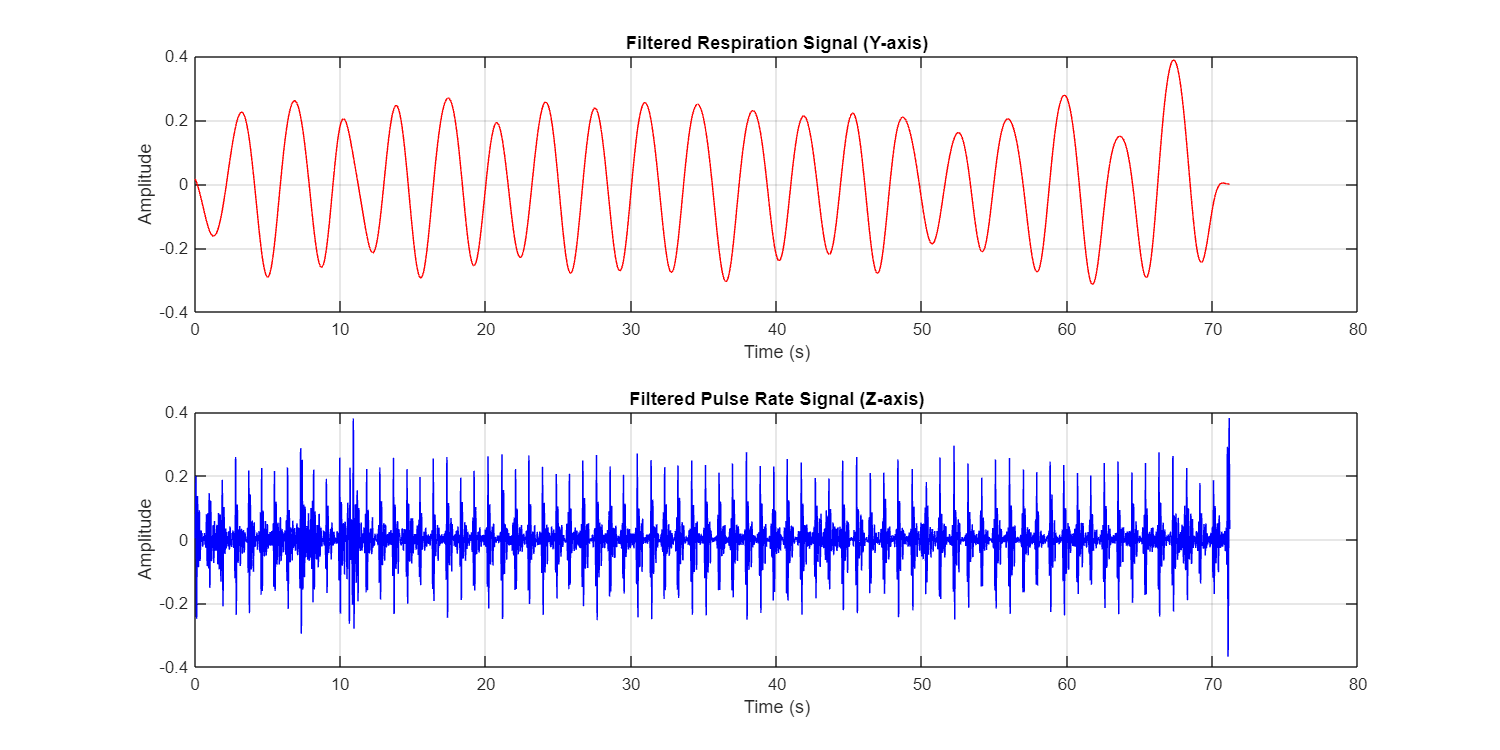

% Plot the filtered pulse rate and respiration data

figure('Name', 'Filtered Pulse Rate and Respiration Signals', 'Position', [100, 100, 1200, 600]);

% First subplot: Respiration Signal (Filtered)
subplot(2, 1, 1);
plot(time, filtered_rr_filtfilt, 'r');
title('Filtered Respiration Signal (Y-axis)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Second subplot: Pulse Rate Signal (Filtered)
subplot(2, 1, 2);
plot(time, filtered_pr_filtfilt, 'b');
title('Filtered Pulse Rate Signal (Z-axis)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

### **Step 9: Spectral Analysis of Filtered Signals**

**Exercise 6:** Perform spectral analysis on the filtered signals to confirm that the filtering has isolated the desired frequency components.

**Instructions:**

- Compute the PSD of the filtered respiration and pulse rate signals

- Plot the PSDs and compare them to the PSDs of the unfiltered signals

- Verify that unwanted frequencies have been attenuated

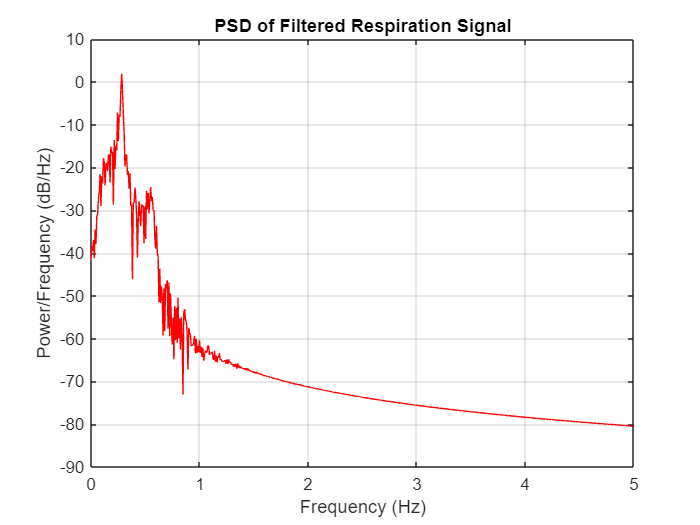

% Compute the PSD of the filtered signals
% --- Your code here ---
[Pxx_rr_filtered, F_rr_filtered] = periodogram();
[Pxx_pr_filtered, F_pr_filtered] = periodogram();

% Plot the PSD of the filtered respiration signal
figure('Name', 'PSD of Filtered Respiration Signal');
plot(F_rr_filtered, 10*log10(Pxx_rr_filtered), 'r');
xlim([0 5]);  % Limit x-axis to 5 Hz
title('PSD of Filtered Respiration Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

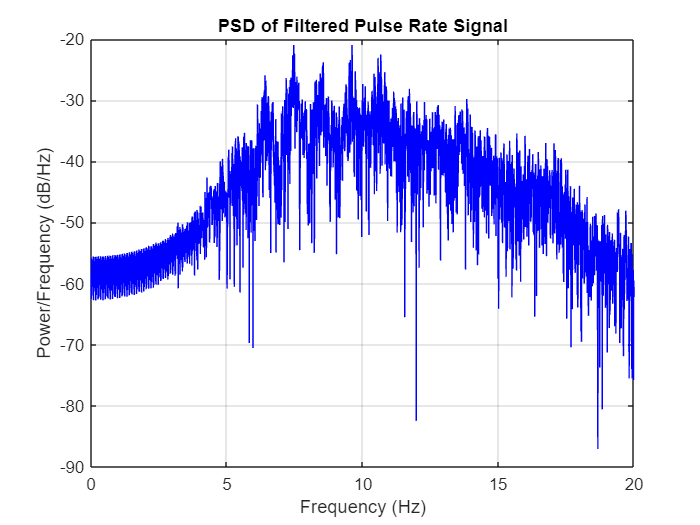

% Plot the PSD of the filtered pulse rate signal
figure('Name', 'PSD of Filtered Pulse Rate Signal');
plot(F_pr_filtered, 10*log10(Pxx_pr_filtered), 'b');
xlim([0 20]);  % Limit x-axis to 10 Hz
title('PSD of Filtered Pulse Rate Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

**Questions:**

- How do the PSDs of the filtered signals compare to those of the unfiltered signals?

- Did the filters effectively isolate the desired frequency components?

### Step 10: Peak Detection for Respiration and Pulse Rate

**Exercise 7:** Implement peak detection on the filtered signals to estimate respiration rate (RR) and pulse rate (PR).

**Instructions:**

- Use the `findpeaks` function to detect peaks in `filtered_rr_filtfilt` and `filtered_pr_filtfilt`

- Choose appropriate values for `MinPeakDistance` based on physiological limits

- Optionally, adjust `MinPeakHeight` to improve peak detection accuracy

The `MinPeakDistance` parameter defines the minimum allowed time between consecutive peaks. It should be based on physiological limits:

- **RR:** The maximum expected rate is 30 breaths per minute (bpm), which corresponds to a minimum interval of 2 seconds between breaths

- **PR:** The maximum expected rate is 120 bpm, meaning the minimum interval between beats is 0.5 seconds

% Define minimum peak distances based on expected physiology
min_peak_dist_rr = ;      % Minimum time between breaths (in seconds)
min_peak_dist_pr = ;    % Minimum time between pulsebeats (in seconds)

% --- Your code here ---
% -- Respiration Peak Detection --
[resp_peaks, resp_locs] = findpeaks();
% -- Pulse Rate Peak Detection --
[pulse_peaks, pulse_locs] = findpeaks();

% Verify number of detected peaks
disp(['Number of Respiration Peaks Detected: ', num2str(length(resp_peaks))]);

Number of Respiration Peaks Detected: 20


disp(['Number of Pulse Peaks Detected: ', num2str(length(pulse_peaks))]);

Number of Pulse Peaks Detected: 78


### **Step 11: Visualize Detected Peaks**

Plot the detected peaks on top of the filtered signals to visually validate the peak detection algorithm.

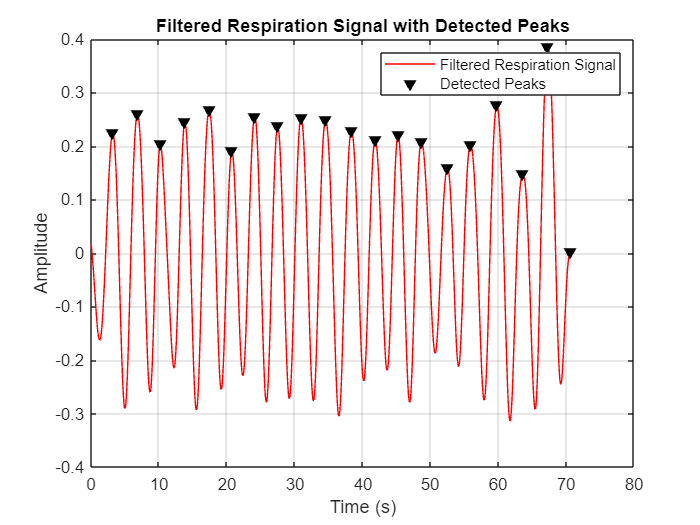

% Plot Respiration Signal with Peaks
figure('Name', 'Filtered Respiration Signal with Detected Peaks');
plot(time, filtered_rr_filtfilt, 'r'); hold on;
plot(resp_locs, resp_peaks, 'kv', 'MarkerFaceColor', 'k');  % Mark peaks with black triangles
title('Filtered Respiration Signal with Detected Peaks');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Filtered Respiration Signal', 'Detected Peaks');
grid on;

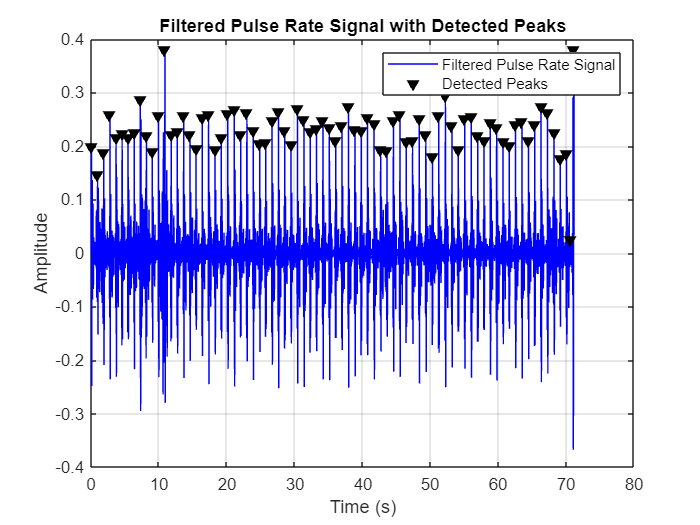

% Plot Pulse Rate Signal with Peaks
figure('Name', 'Filtered Pulse Rate Signal with Detected Peaks');
plot(time, filtered_pr_filtfilt, 'b'); hold on;
plot(pulse_locs, pulse_peaks, 'kv', 'MarkerFaceColor', 'k');  % Mark peaks with black triangles
title('Filtered Pulse Rate Signal with Detected Peaks');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Filtered Pulse Rate Signal', 'Detected Peaks');
grid on;

% Enable interactive zooming
%zoom on;  % Turns on zooming for this figure

### **Step 12: Calculate Respiration Rate (RR) and Pulse Rate (PR)**

After detecting peaks, we can calculate the RR in breaths per minute and the PR in beats per minute.

**Exercise 8:** Calculate RR and PR from the detected peaks

**Instructions:**

- Compute the intervals between peaks for both respiration and pulse rate

- Calculate the instantaneous RR and PR

- Compute the average RR and PR over the entire signal duration

% -- Respiration Rate Calculation (RR in breaths per minute) --
% --- Your code here ---
resp_intervals = ;            % Time differences between successive respiration peaks (in seconds)
resp_rate = ;                 % Convert intervals to breaths per minute
avg_resp_rate = ;             % Calculate the average respiration rate

% -- Pulse Rate Calculation (PR in beats per minute) --
% --- Your code here ---
pulse_intervals = ;          % Time differences between successive pulse peaks (in seconds)
pulse_rate = ;               % Convert intervals to beats per minute
avg_pulse_rate = ;           % Calculate the average pulse rate

% Display the results
disp(['Average Respiration Rate: ', num2str(avg_resp_rate), ' breaths per minute']);

Average Respiration Rate: 16.9329 breaths per minute


disp(['Average Pulse Rate: ', num2str(avg_pulse_rate), ' beats per minute']);

Average Pulse Rate: 65.5443 beats per minute


**Questions:**

- Are the calculated average RR and PR within normal physiological ranges?

- How do these values compare to the ones you recorded manually during the experiments?

### **[ Optional ] Step 13: Estimating Pulse Rate from the Envelope of the Filtered Signal**

**Background:**

In seismocardiography (SCG) signals, the mechanical vibrations caused by pulsebeats can produce complex waveforms with multiple peaks within a single cardiac cycle. This can make peak detection on the raw or even filtered SCG signal challenging. To improve the reliability of pulse rate estimation, we can compute the **envelope** of the filtered pulse rate signal. **The envelope represents the overall amplitude modulation of the signal, highlighting the periodicity corresponding to pulsebeats.**

**Why Use the Envelope?**

- **Simplifies the Signal:** The envelope smooths out high-frequency variations, emphasizing the general shape of the waveform

- **Highlights Periodicity:** The periodic nature of the pulsebeats becomes more apparent in the envelope, making peak detection more reliable

- **Reduces Noise Influence:** The envelope can help mitigate the effects of high-frequency noise and artifacts

**How to Obtain the Envelope:**

- Use the **Hilbert Transform** to compute the analytical signal

- The magnitude (absolute value) of the analytical signal is the envelope of the original signal

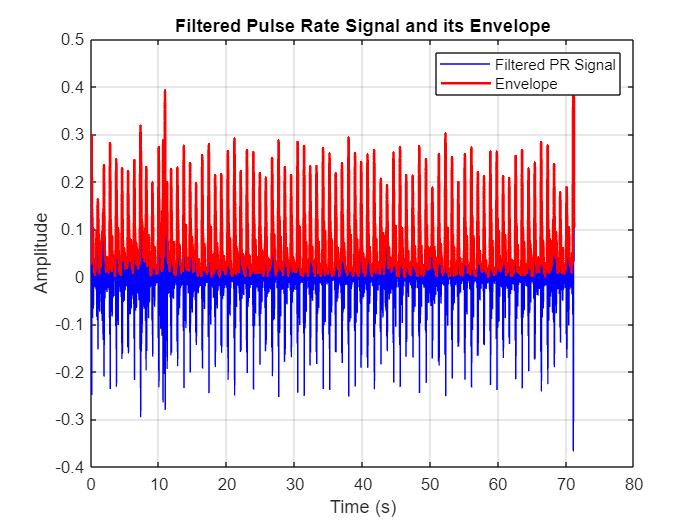

% Compute the envelope of the filtered pulse rate signal
envelope_pr = abs(hilbert(filtered_pr_filtfilt));

% Plot the envelope over the filtered pulse rate signal
figure('Name', 'Filtered Pulse Rate Signal and its Envelope');
plot(time, filtered_pr_filtfilt, 'b'); hold on;
plot(time, envelope_pr, 'r', 'LineWidth', 1.5);
title('Filtered Pulse Rate Signal and its Envelope');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Filtered PR Signal', 'Envelope');
grid on;

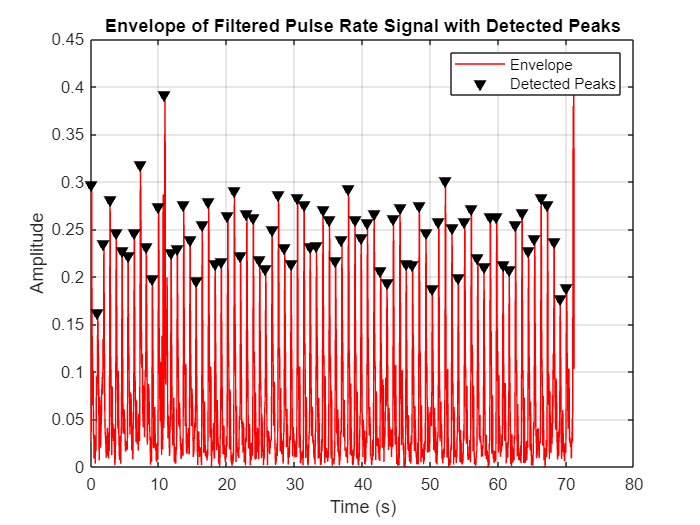

% Perform peak detection on the envelope
min_peak_dist_pr = 0.5;  % Minimum time between pulsebeats (in seconds)
[envelope_peaks, envelope_locs] = findpeaks(envelope_pr, time, 'MinPeakDistance', min_peak_dist_pr);

% Plot the envelope with detected peaks
figure('Name', 'Envelope of Filtered Pulse Rate Signal with Detected Peaks');
plot(time, envelope_pr, 'r'); hold on;
plot(envelope_locs, envelope_peaks, 'kv', 'MarkerFaceColor', 'k');  % Mark peaks with black triangles
title('Envelope of Filtered Pulse Rate Signal with Detected Peaks');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Envelope', 'Detected Peaks');
grid on;

% Calculate Pulse Rate from Envelope Peaks
pulse_intervals_env = diff(envelope_locs);          % Time differences between successive pulse peaks (in seconds)
pulse_rate_env = 60 ./ pulse_intervals_env;         % Convert intervals to beats per minute
avg_pulse_rate_env = mean(pulse_rate_env);          % Calculate the average pulse rate

% Display the results
disp(['Average Pulse Rate from Envelope Peak Detection: ', num2str(avg_pulse_rate_env), ' beats per minute']);

Average Pulse Rate from Envelope Peak Detection: 64.2676 beats per minute


**Notes:**

- Comparing the average pulse rate obtained from peak detection on the envelope to the one obtained earlier can provide insights into the effectiveness of this method

- **You are not required to code this step; the code is provided for you to run and observe the results**

**Questions:**

- How does the average pulse rate obtained from the envelope compare to that obtained from peak detection on the filtered signal?

- What are the advantages of using the envelope for pulse rate estimation in SCG signals?

### Step 14: Pulse rate and Respiration Rate Change Over Time

Visualize how pulse rate and respiration rate change over time by plotting the rates at each detected peak.

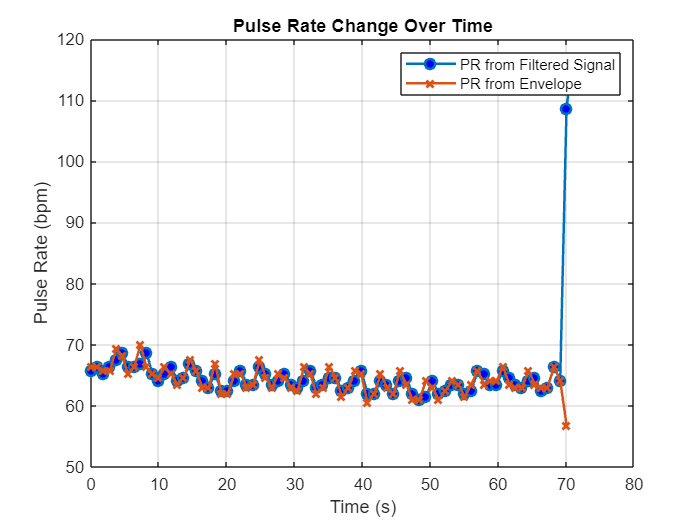

% Time Points for PR and RR
pr_time = pulse_locs(1:end-1);                % Time points for pulse rate, corresponding to the intervals
rr_time = resp_locs(1:end-1);                 % Time points for respiration rate, corresponding to the intervals
pr_env_time = envelope_locs(1:end-1);         % Time points for envelope-based pulse rate

% Plot PR Change Over Time (from filtered signal)
figure('Name', 'Pulse Rate Change Over Time');
plot(pr_time, pulse_rate, '-o', 'MarkerFaceColor', 'b', 'LineWidth', 1.5);
hold on;
% Plot PR Change Over Time (from envelope)
plot(pr_env_time, pulse_rate_env, '-x', 'MarkerFaceColor', 'r', 'LineWidth', 1.5);
title('Pulse Rate Change Over Time');
xlabel('Time (s)');
ylabel('Pulse Rate (bpm)');
legend('PR from Filtered Signal', 'PR from Envelope');
grid on;

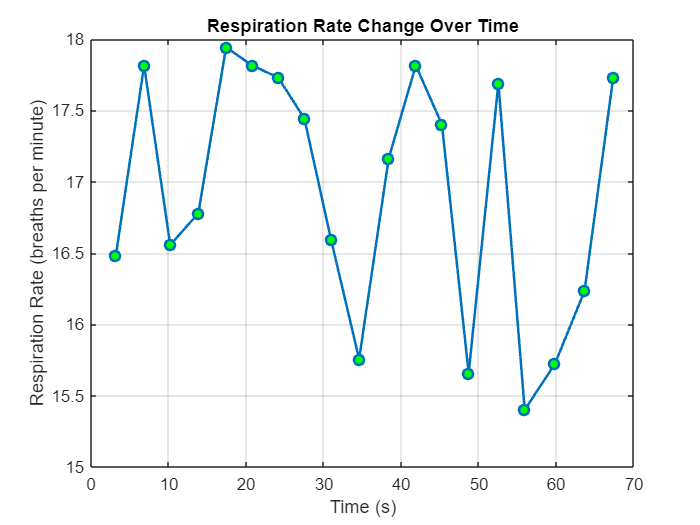

% Plot RR Change Over Time
figure('Name', 'Respiration Rate Change Over Time');
plot(rr_time, resp_rate, '-o', 'MarkerFaceColor', 'g', 'LineWidth', 1.5);
title('Respiration Rate Change Over Time');
xlabel('Time (s)');
ylabel('Respiration Rate (breaths per minute)');
grid on;
grid on;

### Step 15: Averaging Pulse Rate and Respiration Rate Over a 1-Minute Measurement Period

To obtain clinically relevant values, we will calculate the average **Pulse Rate (PR)** and **Respiration Rate (RR)** over the first 60 seconds (1 minute) of data.

**Exercise 9:** Calculate the average PR and RR over the first 60 seconds (1 minute) of data.

**Instructions:**

- Ensure that your data covers at least 60 seconds

- Extract peaks within the first 60 seconds

- Calculate the average PR and RR over this period

% Step: Calculate PR and RR Over the First 60 Seconds

% Define the measurement period (e.g., first 60 seconds)
measurement_period = 60;  % in seconds

% Ensure the data covers at least 60 seconds
if max(time) < measurement_period
    error('Data duration is less than the measurement period.');
end

% Find indices corresponding to the measurement period
measurement_indices_pr = pulse_locs <= measurement_period;
measurement_indices_rr = resp_locs <= measurement_period;
measurement_indices_pr_env = envelope_locs <= measurement_period;

% Extract pulse rate peaks within the measurement period (filtered signal)
% --- Your code here ---
pulse_locs_period = ;
pulse_intervals_period = ;
pulse_rate_period = ;  % Convert to bpm
avg_pulse_rate_period = ;   % Average pulse rate over the first 60s

% Extract pulse rate peaks within the measurement period (envelope)
% --- Your code here ---
envelope_locs_period = ;
pulse_intervals_env_period = ;
pulse_rate_env_period = ;  % Convert to bpm
avg_pulse_rate_env_period = ;   % Average pulse rate over the first 60s

% Extract respiration rate peaks within the measurement period
% --- Your code here ---
resp_locs_period = ;
resp_intervals_period = ;
resp_rate_period = ;    % Convert to breaths per minute
avg_resp_rate_period = ;     % Average respiration rate over the first 60s

% Display the averaged results
disp(['Average Pulse Rate (Filtered Signal) over the first ', num2str(measurement_period), ' seconds: ', num2str(avg_pulse_rate_period), ' bpm']);

Average Pulse Rate (Filtered Signal) over the first 60 seconds: 64.363 bpm


disp(['Average Pulse Rate (Envelope Signal) over the first ', num2str(measurement_period), ' seconds: ', num2str(avg_pulse_rate_env_period), ' bpm']);

Average Pulse Rate (Envelope Signal) over the first 60 seconds: 64.3994 bpm


disp(['Average Respiration Rate over the first ', num2str(measurement_period), ' seconds: ', num2str(avg_resp_rate_period), ' breaths per minute']);

Average Respiration Rate over the first 60 seconds: 17.0023 breaths per minute


**Questions:**

- How do the average PR and RR over the first 60 seconds compare to the averages over the entire signal?

- Why is it clinically relevant to average PR and RR over a fixed period?

### **Step 16: Compare Averaged Values with Manual Measurements**

**Exercise 10:** Compare the 1-minute averaged values extracted from the processed signal with your manual measurements.

**Instructions:**

- Use the manually recorded PR and RR values you noted earlier

- Calculate the percentage error between the manually recorded values and the values extracted from the accelerometer data

- Discuss possible reasons for any discrepancies

% Replace with your manually recorded values for the measurement being analyzed
% For example, if analyzing Measurement 1 for Student 1:
manual_PR = ; % M1_PR = ; % Manually recorded pulse rate (from PulseOx sensor)
manual_RR = ; % M1_RR = ; % Manually counted respiration rate

% Use the averaged values calculated from the data
extracted_PR = avg_pulse_rate_period;  % From the accelerometer data
extracted_RR = avg_resp_rate_period;   % From the accelerometer data

% Calculate percentage error
error_PR = ((extracted_PR - manual_PR) / manual_PR) * 100;
error_RR = ((extracted_RR - manual_RR) / manual_RR) * 100;

% Display the errors
disp(['Percentage Error in Pulse Rate: ', num2str(error_PR), '%']);

Percentage Error in Pulse Rate: -0.97999%


disp(['Percentage Error in Respiration Rate: ', num2str(error_RR), '%']);

Percentage Error in Respiration Rate: 6.2646%


**Questions:**

- How close are the extracted values to the manually recorded values?

- What factors could contribute to any differences observed?

- How might the accuracy of manual measurements affect the comparison?

### **Step 17: Analyze the Impact of Motion Artifacts**

**Exercise 11:** Apply the same analysis to accelerometry data with intentionally induced motion artifacts.

**Instructions:**

- Load the artifact-induced data.

- Repeat the preprocessing, spectral analysis, filtering, and peak detection steps.

- Compare the results to those obtained from the clean data.

**Questions:**

- How do motion artifacts affect the accuracy of HR and RR estimation?

- What strategies can be employed to mitigate the impact of motion artifacts?

### **[ Optional ] Step 18: Estimating PR and RR from the PSD **

**Background:**

In addition to time-domain methods, we can estimate pulse rate (PR) and respiration rate (RR) by analyzing the frequency content of the signals. For RR, analyzing the Power Spectral Density (PSD) of the filtered respiration signal can reveal the dominant frequency corresponding to the respiration rate. For PR, we compute the PSD of the envelope of the filtered pulse rate signal to estimate PR.

**Why Use PSD for Estimating PR and RR?**

**Respiration Rate (RR):**

- The respiration signal is dominated by low-frequency components corresponding to breathing cycles

- Analyzing the PSD of the filtered respiration signal directly highlights the dominant frequency associated with RR.

**Pulse Rate (PR):**

- The SCG pulse signal contains multiple high-frequency components due to mechanical events within each pulsebeat

- Computing the envelope of the filtered pulse rate signal emphasizes the periodicity corresponding to pulsetbeats, making the PR frequency more prominent in the PSD

**Demonstration:**

In this step, you will explore how to estimate RR and PR from the PSD of the signals. The code is provided below. Run the code, observe the results, and understand how frequency-domain analysis can be used for physiological signal estimation.

**Understanding the Code:**

**RR Estimation:**

- The PSD of the filtered respiration signal is computed using the `periodogram` function

- The dominant frequency within the expected RR range is identified

- This frequency is converted to breaths per minute

**PR Estimation:**

- The envelope of the filtered pulse rate signal is computed using the Hilbert Transform

- The PSD of the envelope signal is computed

- The dominant frequency within the expected PR range is identified

- This frequency is converted to beats per minute

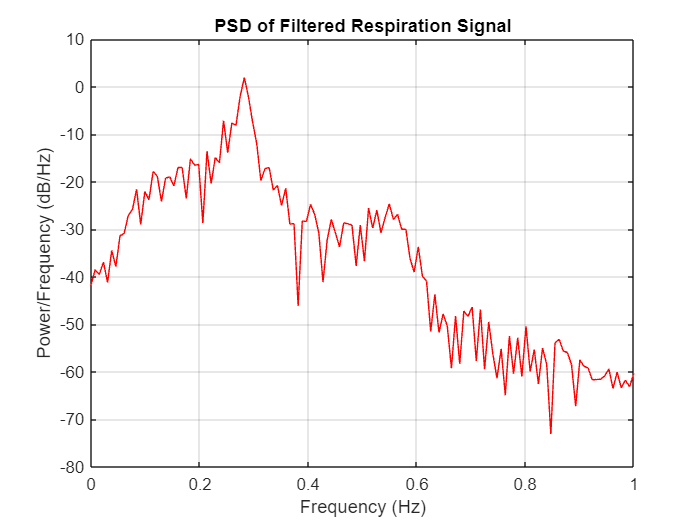

% -- Estimating Respiration Rate from PSD of Filtered Respiration Signal --

% Compute the PSD of the filtered respiration signal
[Pxx_rr_psd, F_rr_psd] = periodogram(filtered_rr_filtfilt, [], [], fs);

% Plot the PSD of the filtered respiration signal
figure('Name', 'PSD of Filtered Respiration Signal');
plot(F_rr_psd, 10*log10(Pxx_rr_psd), 'r');
xlim([0 1]);  % Limit x-axis to 1 Hz
title('PSD of Filtered Respiration Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

% Identify dominant frequency for respiration rate
rr_freq_range = [0.1, 0.5];  % Corresponds to 6 bpm to 30 bpm
rr_indices = find(F_rr_psd >= rr_freq_range(1) & F_rr_psd <= rr_freq_range(2));
[~, idx_rr_peak] = max(Pxx_rr_psd(rr_indices));
dominant_rr_freq = F_rr_psd(rr_indices(idx_rr_peak));
estimated_rr_bpm_psd = dominant_rr_freq * 60;
disp(['Estimated Respiration Rate from PSD: ', num2str(estimated_rr_bpm_psd), ' breaths per minute']);

Estimated Respiration Rate from PSD: 16.9373 breaths per minute


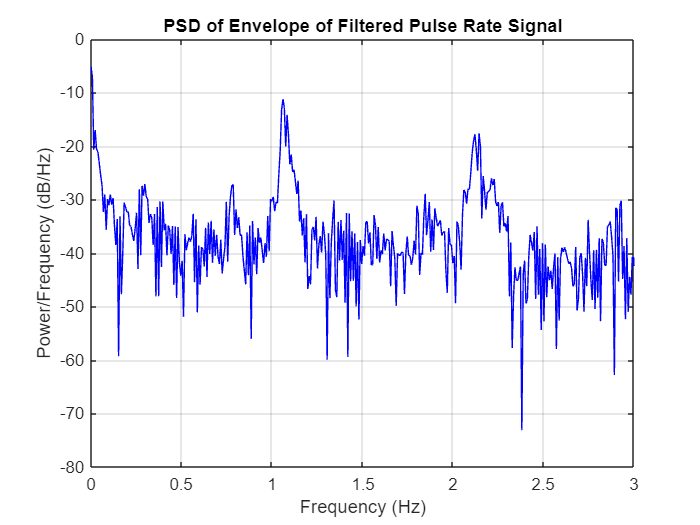

% -- Estimating Pulse Rate from PSD of Envelope of Filtered Pulse Rate Signal --

% The envelope_hr was computed earlier using:
% envelope_hr = abs(hilbert(filtered_hr_filtfilt));

% Compute the PSD of the envelope of pulse rate signal
[Pxx_env_pr, F_env_pr] = periodogram(envelope_pr, [], [], fs);

% Plot the PSD of the envelope of pulse rate signal
figure('Name', 'PSD of Envelope of Filtered Pulse Rate Signal');
plot(F_env_pr, 10*log10(Pxx_env_pr), 'b');
xlim([0 3]);  % Limit x-axis to 3 Hz
title('PSD of Envelope of Filtered Pulse Rate Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

% Identify dominant frequency for pulse rate
pr_freq_range = [0.5, 3];  % Corresponds to 30 bpm to 180 bpm
pr_indices = find(F_env_pr >= pr_freq_range(1) & F_env_pr <= pr_freq_range(2));
[~, idx_pr_peak] = max(Pxx_env_pr(pr_indices));
dominant_pr_freq = F_env_pr(pr_indices(idx_pr_peak));
estimated_pr_bpm_env = dominant_pr_freq * 60;
disp(['Estimated Pulse Rate from PSD of Envelope: ', num2str(estimated_pr_bpm_env), ' beats per minute']);

Estimated Pulse Rate from PSD of Envelope: 63.6292 beats per minute


**Interpretation:**

- Compare these estimates with those obtained from time-domain peak detection

- Consider the advantages and limitations of estimating PR and RR from the PSD

**Questions to Consider:**

- How do the PR and RR estimates from the PSD compare to those from time-domain peak detection?

- What are the advantages and limitations of estimating PR and RR from the PSD?

**Notes:**

- This step is optional and intended for students interested in exploring alternative methods of PR and RR estimation

- It can provide insights into frequency-domain analysis and its applications in physiological signal processing

- **You are not required to code this step; the code is provided for you to run and observe the results**

### **[Optional] Step 19: Exploring Interaction Between Pulse Rate and Respiration Rate**

Respiratory Sinus Arrhythmia (RSA) is a natural variation in pulse rate that occurs during the breathing cycle. Typically, the pulse rate increases during inspiration and decreases during expiration. This interaction results from autonomic nervous system regulation and is more pronounced in some individuals.

**Why Explore PR and RR Interaction?**

- **Physiological Understanding:** Observing RSA can enhance understanding of autonomic cardiovascular control

- **Signal Processing Challenge:** Differentiating between physiological variations and artifacts is crucial in signal analysis

**Demonstration:**

In this step, you will explore the interaction between pulse rate and respiration. The provided code will help you analyze pulse rate variability in relation to the respiration cycle. Run the code, observe the results, and consider the physiological implications.

**Understanding the Code:**

- **Extract Instantaneous Pulse Rate:** Obtains pulse rate values and their corresponding times from the detected peaks

- **Resample Respiration Signal:** Aligns the respiration signal with the pulse rate time points for accurate comparison

- **Visualize Data:** Plots the instantaneous pulse rate alongside the respiration signal to visually assess potential correlations

% Extract instantaneous pulse rate and corresponding times
pr_times = pulse_locs(1:end-1);
instantaneous_pr = pulse_rate;

% Ensure instantaneous_pr is a column vector
instantaneous_pr = instantaneous_pr(:);

% Resample the respiration signal to match the pulse rate time points
resp_signal_resampled = interp1(time, filtered_rr_filtfilt, pr_times, 'linear');

% Ensure resp_signal_resampled is a column vector
resp_signal_resampled = resp_signal_resampled(:);

% Check for NaN values resulting from interpolation
num_NaNs = sum(isnan(resp_signal_resampled));
disp(['Number of NaNs in resp_signal_resampled: ', num2str(num_NaNs)]);

Number of NaNs in resp_signal_resampled: 0


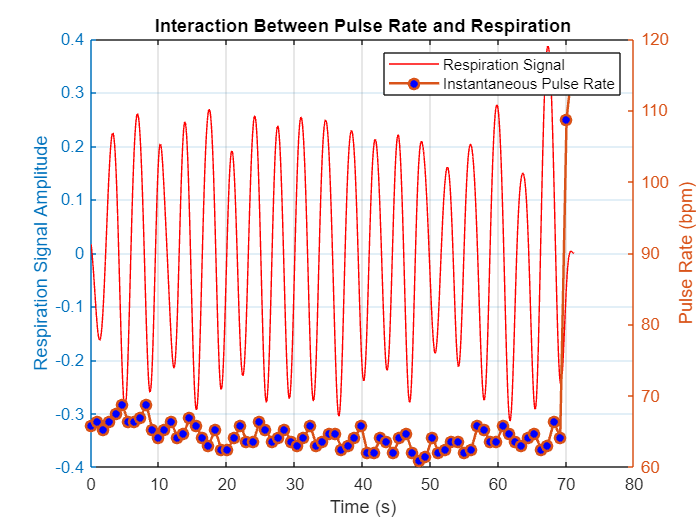


% Handle NaN values if any
if num_NaNs > 0
    % Identify valid indices
    valid_indices = ~isnan(resp_signal_resampled) & ~isnan(instantaneous_pr);
    
    % Keep only valid data
    instantaneous_pr = instantaneous_pr(valid_indices);
    resp_signal_resampled = resp_signal_resampled(valid_indices);
    pr_times = pr_times(valid_indices); % Update pr_times accordingly
end

% Plot instantaneous pulse rate and respiration signal
figure('Name', 'Interaction Between Pulse Rate and Respiration');

% Plot respiration signal (Filtered Respiration Signal)
yyaxis left
plot(time, filtered_rr_filtfilt, 'r');
ylabel('Respiration Signal Amplitude');

% Plot instantaneous pulse rate
yyaxis right
plot(pr_times, instantaneous_pr, '-o', 'MarkerFaceColor', 'b', 'LineWidth', 1.5);
ylabel('Pulse Rate (bpm)');

xlabel('Time (s)');
title('Interaction Between Pulse Rate and Respiration');
legend('Respiration Signal', 'Instantaneous Pulse Rate');
grid on;

**Interpretation:**

**    Visual Analysis:**

- Observe how the pulse rate values align with the respiration signal

- Look for patterns where the pulse rate increases during inhalation (when the respiration signal peaks) and decreases during exhalation (when the respiration signal troughs)

**    Consider Physiological Factors:**

- RSA may not be pronounced in all individuals

- The strength of RSA can vary based on factors like age, fitness level, and breathing patterns

**Questions to Consider:**

- Do you observe changes in pulse rate that correspond with the phases of the respiration cycle?

- Is there visual evidence of respiratory sinus arrhythmia in your data?

- What factors might influence the visibility of this interaction in different individuals?

**Notes:**

- This step is optional and provides an opportunity to explore the physiological interaction between pulse rate and respiration

- Understanding RSA can deepen your insight into how the autonomic nervous system regulates cardiovascular function

- **You are not required to code this step; the code is provided for you to run and observe the results**

## Conclusion

In this lab, you applied signal processing techniques to real-world accelerometry data to extract pulse rate (PR) and respiration rate (RR). After resampling the data to ensure uniformly spaced time intervals, you performed spectral analysis to identify the dominant frequency components corresponding to PR and RR. Based on the spectral analysis, you designed and applied Butterworth bandpass filters to isolate the pulse and respiration components of the signal. You performed peak detection to estimate PR and RR, and calculated their averages over a clinically relevant 1-minute period.

You also explored the use of the envelope of the filtered pulse rate signal to improve PR estimation and observed how spectral analysis of the envelope can provide alternative methods for estimating PR and RR. This approach emphasizes the importance of spectral analysis and advanced signal processing techniques in understanding the frequency characteristics of physiological signals and designing appropriate methods for accurate measurement.

**Final Reflective Questions**

- How did the spectral analysis influence your choice of filter parameters (e.g., cutoff frequencies and filter order) for PR and RR?

- What are the clinical implications of averaging PR and RR over a fixed period (e.g., 1 minute)?

- Why is it important to perform spectral analysis before filter design when working with accelerometry data?

- What advantages did using the envelope of the SCG signal provide in estimating PR?

- How do motion artifacts impact the accuracy of the detected peaks, and how might spectral analysis help in identifying and removing these artifacts?

### Note to Students

Understanding the code and the underlying concepts is crucial. While tools like ChatGPT and built-in MATLAB functions can assist with code generation, developing a deep comprehension of the material will enable you to apply these techniques effectively in practical situations and troubleshoot issues that automated tools cannot anticipate.

## End of Lab